# Introduction to Matlab: Matrices, Graphics and programming

#### Xavier Martin Ballesteros, Adrià Cabeza Sant'Anna (Grup 12L)

20/02/2019

## Desktop Tools and Development Environment 

### 1) Tutorials about the environment

#### 1.3  Indicate what the command history is and list two ways to repeat the evaluation previously executed expression.

To indicate which are the commands we have typed before:

commandhistory

Then if we want to repeat the evaluation of a previously executed expression we can use the up arrow in the command window and select the desired command, using the *commandhistory* command and use the pop-up window or using the command history layout avaliable here: HOME > LAYOUT > COMMAND HISTORY.

#### 1.4  Indicate what the current folder window is used for. How can be some visualization options changed?

The current folder window indicates the folder you are working in and all the files you have available. You can change some visualization options following this path: CURRENT FOLDER > ARROW DOWN BUTTON > (SHOW | SORT BY | GROUP BY).

## Matrices 

### 2) Basic matrix operations, Matrix manipulation

**2.1**

v1 = [12,23,54,8,6]

v1 =     12    23    54     8     6


**2.2**

v2 = v1 + 10

v2 =     22    33    64    18    16


**2.3**

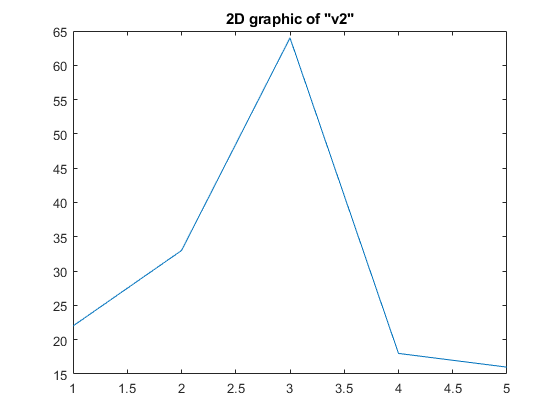

plot(v2), title('2D graphic of "v2"')

**2.4**

M = [1,4,22,7;
    9,2,3,11;
    49,55,6,3;
    24,7,9,12]

M =      1     4    22     7
     9     2     3    11
    49    55     6     3
    24     7     9    12


**2.5**

Mt = M'

Mt =      1     9    49    24
     4     2    55     7
    22     3     6     9
     7    11     3    12


**2.6**

Mi = inv(M)

Mi =    -0.0223   -0.0755   -0.0063    0.0838
    0.0150    0.0651    0.0242   -0.0744
    0.0425   -0.0583   -0.0048    0.0298
    0.0039    0.1567    0.0021   -0.0631


**2.7**

M * Mi

ans =     1.0000         0   -0.0000         0
   -0.0000    1.0000   -0.0000    0.0000
    0.0000    0.0000    1.0000   -0.0000
   -0.0000    0.0000    0.0000    1.0000


`2.8`

ans

ans =     1.0000         0   -0.0000         0
   -0.0000    1.0000   -0.0000    0.0000
    0.0000    0.0000    1.0000   -0.0000
   -0.0000    0.0000    0.0000    1.0000


`2.9`

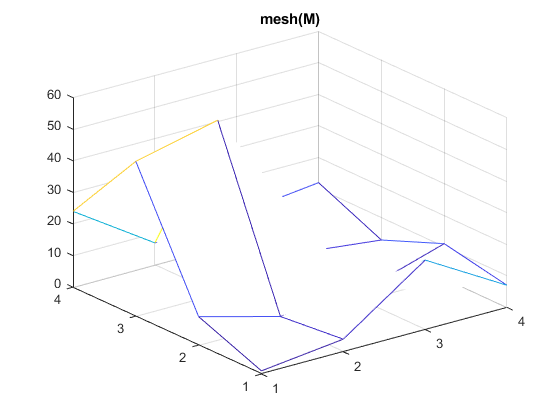

mesh(M), title('mesh(M)')

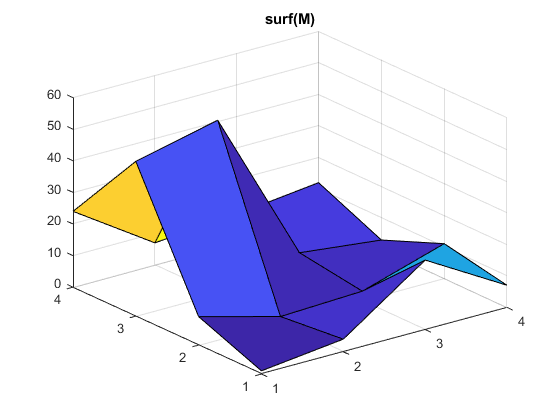

surf(M), title('surf(M)')

## Graphics

### 3) 2D Plots

#### **3.1) What does the "x = 0:0.05:5;" expression?**

It creates the vector starting from 0 to 5 using a 0.05 stride.

x = 0:0.05:5

x =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


#### `3.2) What does the "bar" function?`

% help bar

This MATLAB function creates a bar graph with one bar for each element.

#### 3.3) `What does the "stairs" function?`

% help stairs

`This MATLAB function draws a stairstep graph of the elements.`

### `4) 3D Plots`

#### `4.1) Indicate and proof what does the "z = peaks(25)" expression.   `

% help peaks

`peaks` is a function of two variables used as an example, obtained by translating and scaling Gaussian distributions. It is useful for demonstrating mesh, surf, pcolor, contour and so on.

#### 4.2) Indicate the difference between *mesh* and *waterfall.*

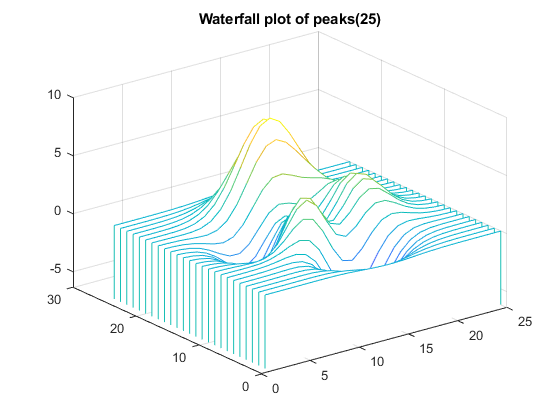

% help waterfall
waterfall(peaks(25)), title('Waterfall plot of peaks(25)')

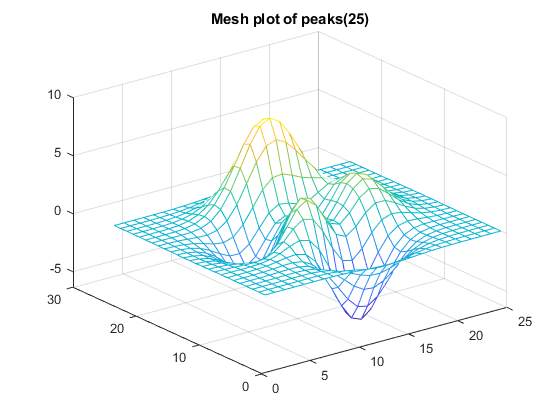

figure, mesh(peaks(25)), title('Mesh plot of peaks(25)')

The `waterfall` function draws a mesh but it does not generate lines from the Y-axis. This produces a “waterfall” effect. 

#### 4.3) Indicate the difference between *surf *and *surfl.*

% help surf
% help surfl

*surf *:   This MATLAB function creates a three-dimensional surface plot.

*surfl*:  This MATLAB function creates three-dimensional shaded surfaces using the default direction for the light source and the default lighting coefficients for the shading model.

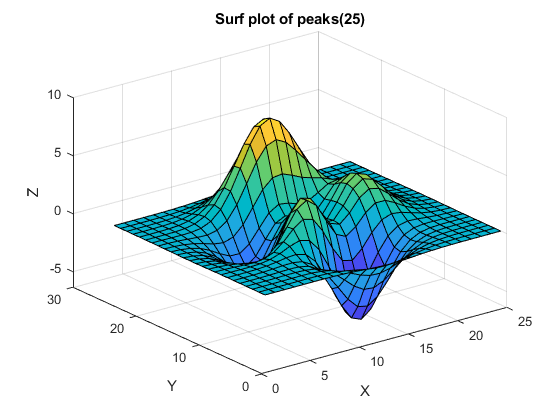

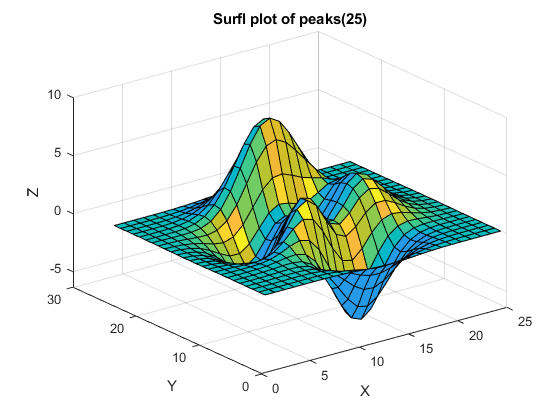

surf(peaks(25)), title('Surf plot of peaks(25)'), ylabel('Y'), xlabel('X'), zlabel('Z')
surfl(peaks(25)), title('Surfl plot of peaks(25)'), ylabel('Y'), xlabel('X'), zlabel('Z')

The main  difference is that the surfl plots a light model and the color depends on that light and surf plots the data and colors it depending on the z-axis.

### 5) Images and Matrices

#### 5.1) Observe the different colormaps that can be applied to indexed images. Indicate three of them and remark the kind of the obtained color when used.

*Hot:* Warm color scale. It goes from black to white passing through red, orange and yellow.

*Gray:* Goes from black to white passing through all kinds of grey.

*Winter:* Cold color scale. It goes from dark blue to turquoise passing through all kinds of blue.

### 6) Line plotting

#### 6.1) Explain what does each one of the demo expressions:

x = 0:0.02:1

x =          0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800


It creates the vector starting from 0 to 1 using a 0.02 stride.

hndl = plot(x, humps(x));

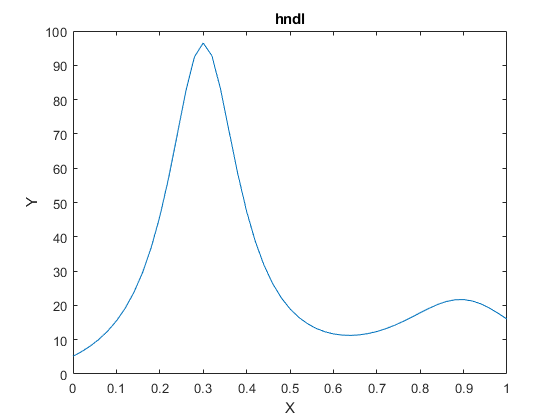

It creates a 2D plot where the previous vector *x* is on the X-axis and *humps(x)* is in the Y-axis.

Humps is a function with strong maxima near x = .3 and x = .9.

set(hndl, 'Color', 'cyan')

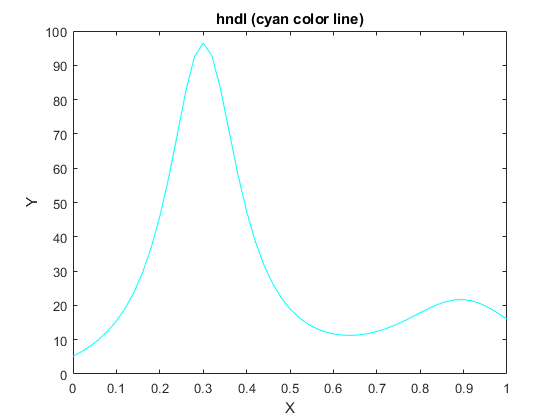

Set function specify the color line of plot *hndl* to **cyan**.

#### 6.2) What is stored in *hndl*?

In *hndl* there is stored a 2D plot.

hndl

hndl =   Line with properties:

              Color: [0 1 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×51 double]
              YData: [1×51 double]
              ZData: [1×0 double]

  Show all properties


#### 6.3) What sentence must be written to change to green the color line?

set(hndl, 'Color', 'green')

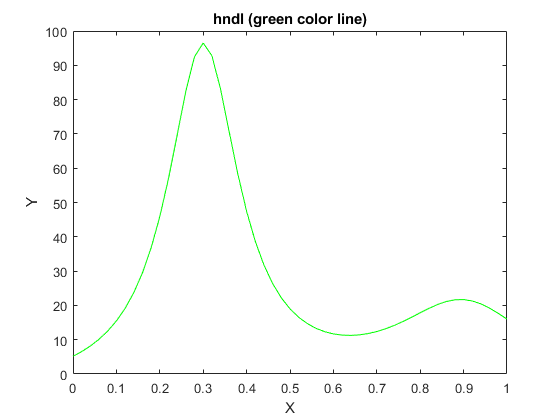

#### 6.4) What sentence must be written to change the line width to 2?

set(hndl, 'LineWidth', 2)

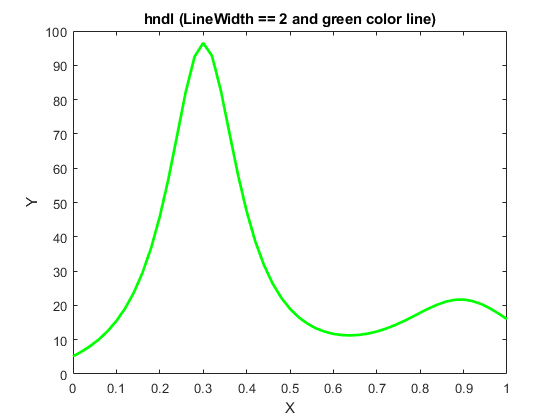

#### 6.5) What sentence must be written to change the line symbol to "o"?

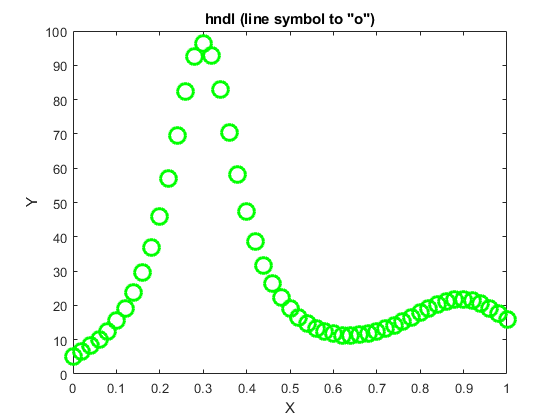

set(hndl, 'LineStyle', 'none')
set(hndl, 'Marker', 'o')
set(hndl, 'MarkerSize', 12), title('hndl (line symbol to "o")'), xlabel('X'), ylabel('Y')

### 7. 3D Surface plots

#### 7.1) Open a new figure, evaluate one by one the following demo lines and indicate what are they used for.

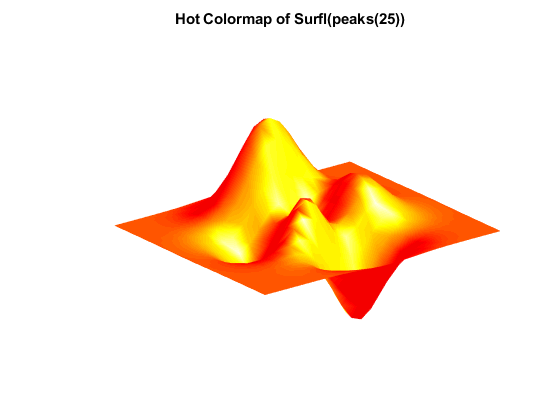

z = peaks(25);
surfl(z)
shading interp
colormap(hot), title('Hot Colormap of Surfl(peaks(25))')
axis off

z = peaks(25) -> uses the sample function peaks and stores the result in the variable z.

surfl(z) -> creates a plot of z using a colormap-based lighting.

shading interp -> variates the color of the surface using interpolation.

colormap(hot) -> it sets the colormap of the plot to a hot colormap.

axis off -> the axis don't appear.

## Programming

### 1) Matlab->Getting Started -> Programming

#### 1.4) Create a function to calculate as many Fibonacci numbers as indicated by the parameter n:

#### Check the property: the sum of ten Fibonnaci consecutive numbers is always eleven times bigger than the seventh number of the series.

res = 0;
for i = 1:10
    res = res + fib(i);
end
res

res = 143

11 * fib(7)

ans = 143

res == 11 * fib(7)

ans = logical
   1


#### 1.5) Does Matlab accept recursivity? Could you find Fibonacci series recursively?

Yes. We have tested it when calling the function *fib*.

Yes, we could find Fibonacci series recursively. However, if we do it using the algorithm given we will not be able to calculate large values of this sequence. Moreover, there is a recursion limit, which is 500.

### 2. Getting Started -> Programming -> Vectorization 

#### 2.1) A simple example involves creating a table of logarithms:

timerVal = tic;
x = 0.01;
for k = 1:1001
    y(k) = log10(x);
    x = x+ .01;
end
toc(timerVal)

Elapsed time is 0.015227 seconds.


#### 2.2) Test results and execution time with a vectorized version (use functions tic and toc)

timerVal = tic;
x = .01:.01:10;
y = log10(x);
toc(timerVal)

Elapsed time is 0.006826 seconds.


### 3. Getting Started -> Programming -> Preallocation

#### 3.1) Run the next code:

timeVal = tic;
for n = 1:200
    r(n) = rank(magic(n));
end
toc(timeVal)

Elapsed time is 0.311855 seconds.


#### 3.2) See the run time benefits of inserting the next sentence before the loop. Test with higher n values.

timeVal = tic;
r = zeros(200,1);
for n = 1:200
    r(n) = rank(magic(n));
end
toc(timeVal)

Elapsed time is 0.310303 seconds.


### 4. Getting Started -> Programming -> Other Data Structures -> Multi-dimensional arrays

####  4.1) What is a multidimensional array?

A multidimensional array is an array that has more than two dimensions.

#### 4.2) Check and indicate what do the next expressions: 

A =[5 7 8; 0 1 9; 4 3 6]

A =      5     7     8
     0     1     9
     4     3     6


It creates the matrix A with those values row-sorted.

A(:,:,2) = [1 0 4;3 5 6; 9 8 7]

A = A(:,:,1) =

     5     7     8
     0     1     9
     4     3     6


A(:,:,2) =

     1     0     4
     3     5     6
     9     8     7


Creates another dimension for the multidimensional array with the values inserted.

#### 4.3) Check the following expressions, write the returned value and indicate what are the differences among them: 

A(1,2)

ans = 7

Accesses to the first row and second column value. By default, it accesses the first dimension.

A(1,2,1)

ans = 7

Accesses to the first row and second column value in the first dimension.

A(1,2,2)

ans = 0

Accesses to the first row and second column value in the second dimension.

#### 4.4) How do you access to the element in the third row, second column in the second dimension?

A(3,2,2)

ans = 8

### 5. Getting Started -> Programming -> Other Data Structures -> Structures

#### *5.2) Create a struct, called personal_record that contains the fileds: name (it must contain an string with your name), age(an scalar) and size (a vector with 3 elements: height, weight and shoe size).*

personal_record = struct('name', 'AdriXavi', 'age', 20, 'size', [1.79, 75, 44])

personal_record = struct with fields:
    name: 'AdriXavi'
     age: 20
    size: [1.7900 75 44]


#### *5.3) Assign to a variable the age stored in the variable personal_record.*

age = personal_record.age

age = 20

#### *5.4) Can be structs nested?, if possible, invent a short example. *

example = struct('ID', 1, 'personal_record', personal_record)

example = struct with fields:
                 ID: 1
    personal_record: [1×1 struct]
